format shortG
ds = [0.9,1.2,1.5,1.8,2.1,2.4,2.7,3,3.3,3.6]; % Distance from the surface of the pitot tube  in mm
Ds = ds * 0.001;        % Convert to meters                        
Patm  = 101325;      % Atmpsoheric pressure kg/ms2
 disp(['Atmpsoheric pressure = ' num2str(Patm)  ' kg/ms2' ])

Atmpsoheric pressure = 101325 kg/ms2


Pwindym  = 538;   % Wind tunnel dynamic pressure kg/ms2
 disp(['Wind tunnel dynamic pressure = ' num2str(Pwindym)  ' kg/ms2' ])

Wind tunnel dynamic pressure = 538 kg/ms2


Ps = Patm - Pwindym;   % Static pressure of the wind tunnel kg/ms2
 disp(['Static pressure = ' num2str(Ps)  ' kg/ms2' ])

Static pressure = 100787 kg/ms2




p = 1000;                    %  kg/m3
g = 9.81;                    %  m/s2
% Distance from the leading edge of the pitot tube  58 mm
hha = [1.21,1.1,1.02,0.93,0.83,0.78,0.68,0.65,0.52,0.49];  % Liquid height of pitot in inches 
ha = hha * 0.0254;                           % Convert to meters 
 disp(['Liquid height of pitot tube = (' num2str(ha)  ') m' ])

Liquid height of pitot tube = (0.030734     0.02794    0.025908    0.023622    0.021082    0.019812    0.017272     0.01651    0.013208    0.012446) m



PT1a = (Patm - (p*g*ha));           % Full pressure of pitot tube  kg/ms2
Pdyma = PT1a - Ps;                  % Dynamic pressure of the pitot tube kg/ms2
 disp(['Dynamic pressure of the pitot tube at 58mm = (' num2str(Pdyma)  ') kg/ms2' ])

Dynamic pressure of the pitot tube at 58mm = (236.4995      263.9086      283.8425      306.2682      331.1856      343.6443      368.5617      376.0369      408.4295      415.9047) kg/ms2


Va = sqrt((2*Pdyma)/1000);           % Velocity m/s
 disp(['Flow speed (Velocity) = (' num2str(Va)  ') m/s' ])

Flow speed (Velocity) = (0.68775     0.72651     0.75345     0.78265     0.81386     0.82903     0.85856     0.86722      0.9038     0.91204) m/s




% Distance from the leading edge of the pitot tube  107 mm
hhb = [1.06,1.02,0.95,0.9,0.82,0.77,0.7,0.69,0.59,0.57];  % Liquid height of pitot in inches 
hb = hhb * 0.0254;                           % Convert to meters 
PT1b = (Patm - (p*g*hb));           % Full pressure of pitot tube  kg/ms2
Pdymb = PT1b - Ps;                  % Dynamic pressure of the pitot tube kg/ms2
 disp(['Dynamic pressure of the pitot tube at 107mm = (' num2str(Pdymb)  ') kg/ms2' ])

Dynamic pressure of the pitot tube at 107mm = (273.8756      283.8425      301.2847      313.7434      333.6773       346.136      363.5782      366.0699      390.9873      395.9708) kg/ms2


Vb = sqrt((2*Pdymb)/1000);           % Velocity m/s
 disp(['Flow speed (Velocity) = (' num2str(Vb)  ') m/s' ])

Flow speed (Velocity) = (0.7401     0.75345     0.77625     0.79214     0.81692     0.83203     0.85273     0.85565     0.88429     0.88991) m/s




% Distance from the leading edge of the pitot tube  156 mm
hhc = [1.23,1.2,1.17,1.11,1.04,1.02,0.93,0.94,0.9,0.92];  % Liquid height of pitot in inches 
hc = hhc * 0.0254;                           % Convert to meters 
PT1c = (Patm - (p*g*hc));           % Full pressure of pitot tube  kg/ms2
Pdymc = PT1c - Ps;                  % Dynamic pressure of the pitot tube kg/ms2
 disp(['Dynamic pressure of the pitot tube at 156mm = (' num2str(Pdymc)  ') kg/ms2' ])

Dynamic pressure of the pitot tube at 156mm = (231.516      238.9912      246.4664      261.4169       278.859      283.8425      306.2682      303.7764      313.7434      308.7599) kg/ms2


Vc = sqrt((2*Pdymc)/1000);           % Velocity m/s
 disp(['Flow speed (Velocity) = (' num2str(Vc)  ') m/s' ])

Flow speed (Velocity) = (0.68046     0.69136     0.70209     0.72307     0.74681     0.75345     0.78265     0.77946     0.79214     0.78582) m/s



% Calculating Reynolds number

U = 30;                            %  Flow speed (Velocity) m/s2
P = 1.204;                            %  density of the fluid kg/m3
L =  [0.058, 0.107, 0.156];              % Length at 58mm, 107mm and 156mm 
u = (1.81*10^-5);                           %  Flow speed (Velocity) m/s2
Re = (U*P*L)/u;                            %  Reynolds number
 disp(['Reynolds numbers: Re = ' num2str(Re) ]);                                                                  

Reynolds numbers: Re = 115743.6464      213527.0718      311310.4972



 disp(['Velocity at 115744 Reynolds number = (' num2str(Va) ' )m/s']);

Velocity at 115744 Reynolds number = (0.68775     0.72651     0.75345     0.78265     0.81386     0.82903     0.85856     0.86722      0.9038     0.91204 )m/s


 
 disp(['Velocity at 213527 Reynolds number = (' num2str(Vb) ' )m/s']);

Velocity at 213527 Reynolds number = (0.7401     0.75345     0.77625     0.79214     0.81692     0.83203     0.85273     0.85565     0.88429     0.88991 )m/s


 
 disp(['Velocity at 311310 Reynolds number = (' num2str(Vc) ' )m/s']);

Velocity at 311310 Reynolds number = (0.68046     0.69136     0.70209     0.72307     0.74681     0.75345     0.78265     0.77946     0.79214     0.78582 )m/s


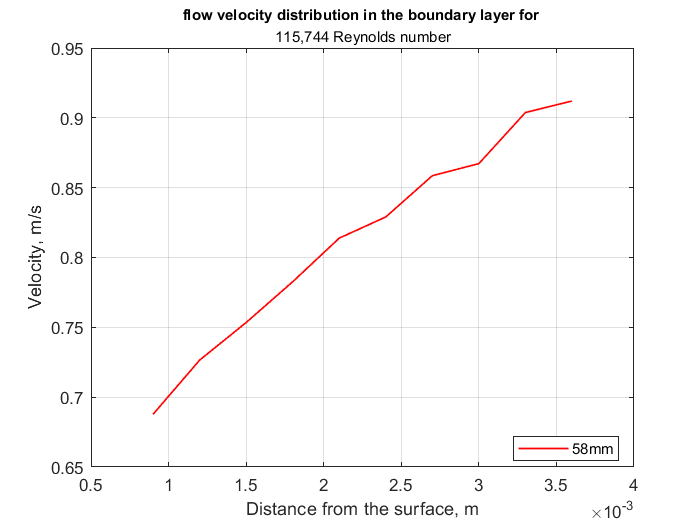

 
  plot(Ds,Va, 'r-','lineWidth',1); 
      title('flow velocity distribution in the boundary layer for ','115,744 Reynolds number','FontSize',9);    % use for title positioning
xlabel('Distance from the surface, m'); 
ylabel('Velocity, m/s');                          
legend('58mm','Location','best');
grid on; 

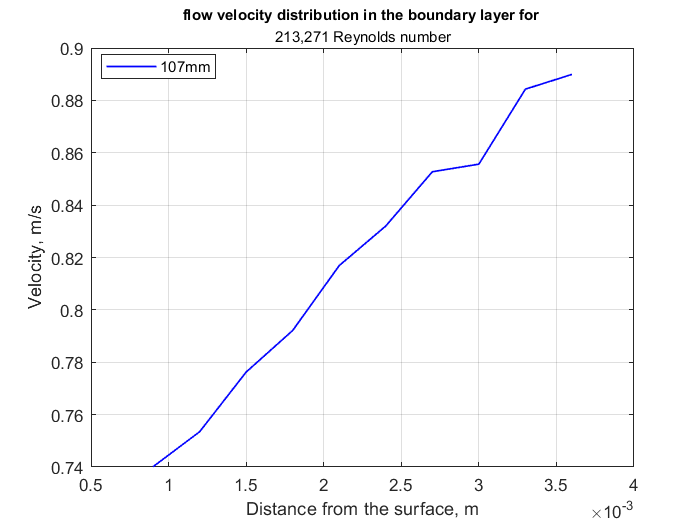



plot(Ds,Vb,'b-','lineWidth',1);  
title('flow velocity distribution in the boundary layer for ','213,271 Reynolds number','FontSize',9);    % use for title positioning
xlabel('Distance from the surface, m'); 
ylabel('Velocity, m/s');                          
legend('107mm','Location','best');
grid on; 

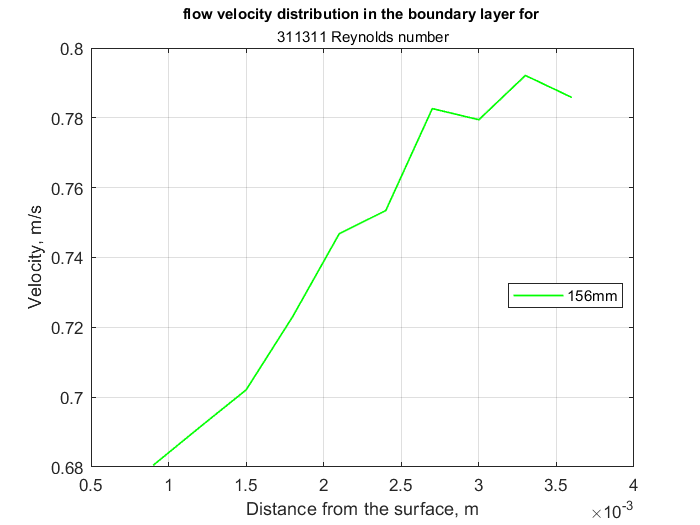



    plot(Ds,Vc,'g-','linewidth',1);
   title('flow velocity distribution in the boundary layer for ','311311 Reynolds number','FontSize',9);    % use for title positioning
xlabel('Distance from the surface, m');  
ylabel('Velocity, m/s');                           
legend('156mm','Location','best');
grid on; 

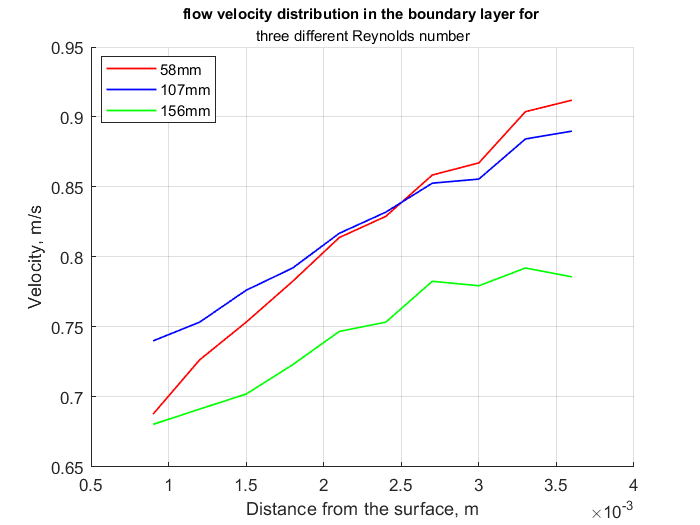


                                      


figure;
sp1 =subplot(1,1,1); hold on;             
    plot(Ds,Va, 'r-','lineWidth',1); 
    plot(Ds,Vb,'b-','lineWidth',1);                                                                                      
    plot(Ds,Vc,'g-','linewidth',1); 
                                                                                                                            


   title('flow velocity distribution in the boundary layer for ','three different Reynolds number','FontSize',9);    % use for title positioning

xlabel('Distance from the surface, m'); 
ylabel('Velocity, m/s');                          
legend({'58mm';'107mm'; '156mm'},'Location','best');
grid on; 